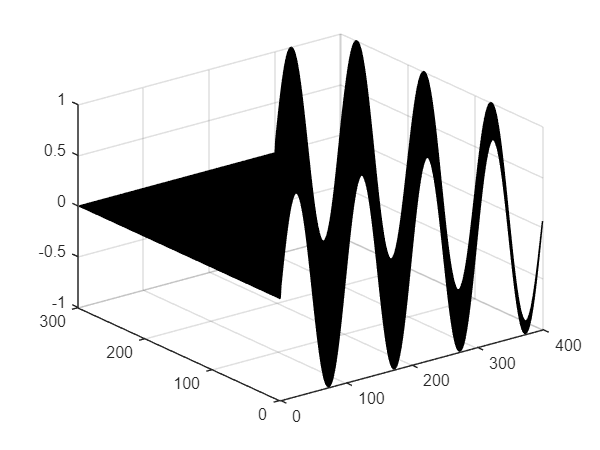

a=0.25;%m/s
L=1;%m
f=1;%Hz
u0=@(t)(sin(2*pi*f*t));
dt=0.01;%s
dx=0.0025;%m
sigma=a*dt/dx;
T=3/f;%duration
Nt=floor(T/dt);
Nx=floor(L/dx);
U=zeros(Nt,Nx);
B=(1-sigma^2)*eye(Nt)+sigma/2*(sigma+1)*diag(ones(1,Nt-1),-1)+sigma/2*(sigma-1)*diag(ones(1,Nt-1),1);
B(1,1)=0;B(1,2)=0;


for i=1:Nx
    U(:,i+1)=B*U(:,i);
    U(1,i+1)=u0((i+1)*dt);
end
surf(U)